clear;
clc;
close all;

%Given
T = 0.1;
K = 600;
omega = zeros(1,K+1);
omega(150:450) = -pi/301/T;
x0 = [0 0 20 0 omega(1)]';
X = zeros(length(x0),K+1);
X(:,1) = x0;
for i = 2:K+1
    X(:,i) = coordinatedTurnMotion(X(:,i-1),T);
    X(5,i) = omega(i);
end


sigma_v = 1*1000;
sigma_w = pi/180*1000;


x_0 = [0 0 0 0 0]';
P_0 = diag([10 10 10 5*pi/180 pi/180].^2);
s1 = [300 -100]';
s2 = [300 -300]';
R = diag([pi/180 pi/180].^2);

gama=[0 0; 0 0; 1 0; 0 0; 0 1];
Q = gama *[sigma_v^2 0; 0 sigma_w^2]*gama'

Q = 1.0e+06 *

         0         0         0         0         0
         0         0         0         0         0
         0         0    1.0000         0         0
         0         0         0         0         0
         0         0         0         0    0.0003


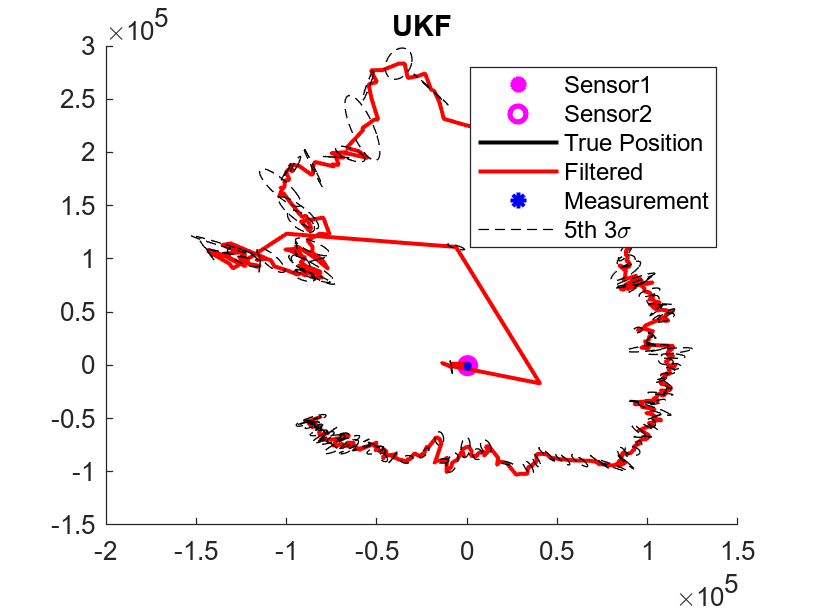


f = @(x) coordinatedTurnMotion(x, T) ;
h = @(x) dualBearingMeasurement(x, s1, s2) ;
% Generate state sequence and measurement sequence
% X = genNonLinearStateSequence(x_0, P_0, f, Q, K);
Y = genNonLinearMeasurementSequence(X, h, R);
[xf,Pf,xp,Pp] = nonLinearKalmanFilter(Y,x_0,P_0,f,Q,h,R,'UKF');

xm(1,:) = ( s2(2)-s1(2) + tan(Y(1,:))*s1(1) - tan(Y(2,:))*s2(1) ) ./ ( tan(Y(1,:)) - tan(Y(2,:)) );
ym(2,:) = s1(2) + tan(Y(1,:)) .* ( xm(1,:) - s1(1) );

figure;
hold on;
%Sensor position
plot(s1(1),s1(2),'*m','Linewidth',2);
plot(s2(1),s2(2),'om','Linewidth',2);
% Plot true positions
plot(X(1,:), X(2,:), 'k-', 'LineWidth', 1.5);
%Plot Filters states
plot(xf(1,:), xf(2,:), 'r-', 'LineWidth', 1.5);

% Plot Dual bearing measurements
sensorx = (s2(2)-s1(2)+tan(Y(1,:))*s1(1)- tan(Y(2,:))*s2(1))./(tan(Y(1,:))- tan(Y(2,:)));
sensory = s1(2)+tan(Y(1,:)).*(sensorx- s1(1));
scatter(sensorx, sensory, 5,'b*', 'LineWidth',1.5)

for i= 1:5:length(xf)
        xy = sigmaEllipse2D(xf(1:2,i), Pf(1:2,1:2,i), 3, 50);
        plot(xy(1,:),xy(2,:),'--k');
end



legend('Sensor1','Sensor2','True Position','Filtered','Measurement','5th 3\sigma ')
title('UKF')


X=X(:,2:end);
error_x = [X(1,:) - xf(1,:)];
error_y = [X(2,:) - xf(2,:)];

figure;
subplot(1,2,1);
hold on;
histogram(error_x, 'Normalization', 'pdf');
mu=mean(error_x)

mu = -7.7109e+03

temp=std(error_x)

temp = 8.2993e+04

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (x)');
ylabel('Probability Density');
title('x position');
text(min(x)/2, max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');

subplot(1,2,2);
hold on;
histogram(error_y, 'Normalization', 'pdf');
mu=mean(error_y)

mu = -2.5965e+04

temp=std(error_y)

temp = 1.0705e+05

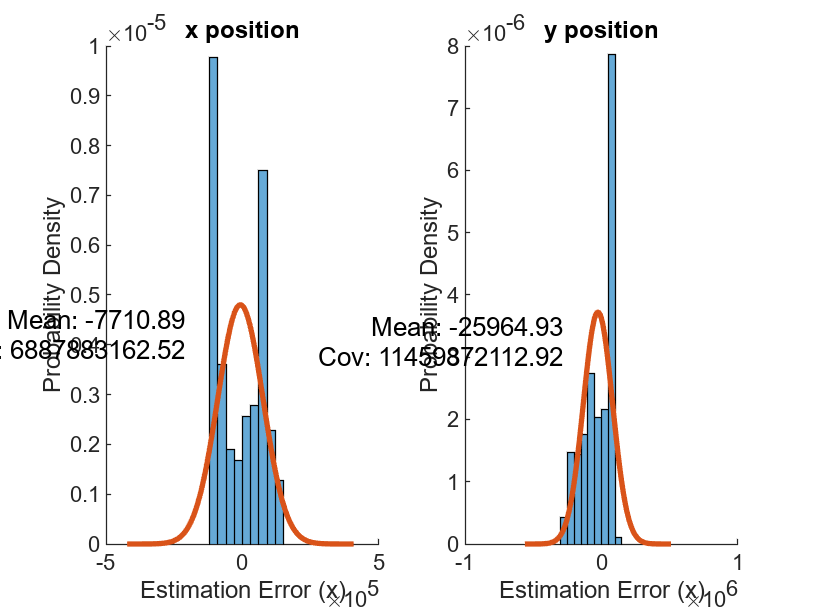

[x,y] = normpdfi(mu, temp^2, 5 ,100);
plot(x,y,'LineWidth',2)
xlabel('Estimation Error (x)');
ylabel('Probability Density');
title('y position');
text(min(x)/2, max(y), sprintf('Mean: %.2f\nCov: %.2f', mu, temp^2), ...
    'HorizontalAlignment', 'right', 'VerticalAlignment', 'top');